# **CS 5487 Programming Assignment 1 part2**

load PA-1-data-matlab/count_data.mat;

## **(a) use the original features, i.e. **$$\phi(x) = x$$**.**

For hyperparameters, we select it by hand, by which I mean I implement chosingHyper function in which calMeanSquaredErr on the test set is envoked to get comparison. (in reality, the real output for test set is not known, like mentioned in part3).

#### **train**

phi_original = trainx;
phi_original_test = testx;
%train
theta_LS = LS(phi_original, trainy);

lambda_RLS = choosingHyper(0.01, 1, 0.01, 5, testx, testy, trainx, trainy, "RLS", "original");
theta_RLS = RLS(phi_original, trainy, lambda_RLS);

lambda_LASSO = choosingHyper(2, 5, 0.001, 5, testx, testy, trainx, trainy, "LASSO", "original");


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

theta_LASSO = LASSO(phi_original, trainy, lambda_LASSO);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



theta_RR = RR(phi_original, trainy);

Optimal solution found.




alpha_BR = choosingHyper(5, 20, 0.1, 5, testx, testy, trainx, trainy, "BR", "original");
[mean_BR, cov_BR] = BR(phi_original, trainy, alpha_BR, 5);

#### prediction

%prediction, we add the ym to make it a positive count
f_LS = phi_original_test' * theta_LS + ym;
f_RLS = phi_original_test' * theta_RLS + ym;
f_LASSO = phi_original_test' * theta_LASSO + ym;
f_RR = phi_original_test' * theta_RR + ym;
f_BR = phi_original_test' * mean_BR + ym;
f_BR_var = phi_original_test' * cov_BR * phi_original_test;
f_BR_pos = f_BR + sqrt(diag(f_BR_var));
f_BR_neg = f_BR - sqrt(diag(f_BR_var));

#### plot

%plot the real function
plot(testy + ym, "r");

%plot the Regression
y_regression_original = [f_LS, f_RLS, f_LASSO, f_RR, f_BR];

hold on
% c = [1 0 0; 0 1 0; 0 0 1; 0 0 0; 0.6350 0.0780 0.1840];
scatter([1:600], y_regression_original, 5);

title("Original Function & Regression");
xlabel("samples");
ylabel("number of people");
legend(["function", "LS", "RLS", "LASSO", "RR", "BR"]);
hold off

#### Mean Absolute Error and Mean Squared Error

- calAbsoluteErr.m which returns the mean absolute error for the output given a real output 

err_squared = zeros(size(y_regression_original, 2), 1);
errlabel = categorical(["LS", "RLS", "LASSO", "RR", "BR"]);
errlabel = reordercats(errlabel,["LS", "RLS", "LASSO", "RR", "BR"]);
for i = 1:size(y_regression_original,2)
    err_squared(i) = calMeanSquaredErr(y_regression_original(:,i), testy + ym);
end
b = bar(errlabel, err_squared);
xlabel("regression method");
ylabel("mean-squared error over all inputs");
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(b.YData);
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')


err_abs = zeros(size(y_regression_original, 2), 1);
errlabel = categorical(["LS", "RLS", "LASSO", "RR", "BR"]);
errlabel = reordercats(errlabel,["LS", "RLS", "LASSO", "RR", "BR"]);
for i = 1:size(y_regression_original,2)
    err_abs(i) = calAbsoluteErr(y_regression_original(:,i), testy + ym);
end
b = bar(errlabel, err_abs);
xlabel("regression method");
ylabel("mean-absolute error over all inputs");
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(b.YData);
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
ylim([0 2]);

#### (b) use other transformation function $$\phi(x)$
$.

For hyperparameters, we select it by hand, by which I mean I implement chosingHyper function in which calMeanSquaredErr on the test set is envoked to get comparison. (in reality, the real output for test set is not known, like mentioned in part3).


$$$\phi(x) = [x_{1}, \ldots, x_{9}, x_{1}^{2}, \ldots, x_{9}^{2}]^{T}$$$


#### **train**

phi_2_nocross = Transform_general(trainx, 2, "nocross");
phi_2_nocross_test = Transform_general(testx, 2, "nocross");
%train
theta_LS = LS(phi_2_nocross, trainy);

lambda_RLS = choosingHyper(0.01, 1, 0.01, 5, testx, testy, trainx, trainy, "RLS", "general_nocross");
theta_RLS = RLS(phi_2_nocross, trainy, lambda_RLS);

lambda_LASSO = choosingHyper(2, 5, 0.001, 5, testx, testy, trainx, trainy, "LASSO", "general_nocross");


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

theta_LASSO = LASSO(phi_2_nocross, trainy, lambda_LASSO);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



theta_RR = RR(phi_2_nocross, trainy);

Optimal solution found.




alpha_BR = choosingHyper(5, 20, 0.1, 5, testx, testy, trainx, trainy, "BR", "general_nocross");
[mean_BR, cov_BR] = BR(phi_2_nocross, trainy, alpha_BR, 5);

#### prediction

%prediction, we add the ym to make it a positive count
f_LS = phi_2_nocross_test' * theta_LS + ym;
f_RLS = phi_2_nocross_test' * theta_RLS + ym;
f_LASSO = phi_2_nocross_test' * theta_LASSO + ym;
f_RR = phi_2_nocross_test' * theta_RR + ym;
f_BR = phi_2_nocross_test' * mean_BR + ym;
f_BR_var = phi_2_nocross_test' * cov_BR * phi_2_nocross_test;
f_BR_pos = f_BR + sqrt(diag(f_BR_var));
f_BR_neg = f_BR - sqrt(diag(f_BR_var));

#### plot

%plot the real function
plot(testy + ym, "r");

%plot the Regression
y_regression_2_nocross = [f_LS, f_RLS, f_LASSO, f_RR, f_BR];

hold on
% c = [1 0 0; 0 1 0; 0 0 1; 0 0 0; 0.6350 0.0780 0.1840];
scatter([1:600], y_regression_2_nocross, 5);

title("Original function & Regression (Second Order Function w/o Cross)");
xlabel("samples");
ylabel("number of people");
legend(["function", "LS", "RLS", "LASSO", "RR", "BR"]);
hold off

#### Mean Absolute Error and Mean Squared Error

- calAbsoluteErr.m which returns the mean absolute error for the output given a real output 

err_squared = zeros(size(y_regression_2_nocross, 2), 1);
errlabel = categorical(["LS", "RLS", "LASSO", "RR", "BR"]);
errlabel = reordercats(errlabel,["LS", "RLS", "LASSO", "RR", "BR"]);
for i = 1:size(y_regression_2_nocross,2)
    err_squared(i) = calMeanSquaredErr(y_regression_2_nocross(:,i), testy + ym);
end
b = bar(errlabel, err_squared);
xlabel("regression method");
ylabel("mean-squared error over all inputs");
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(b.YData);
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')


err_abs = zeros(size(y_regression_2_nocross, 2), 1);
errlabel = categorical(["LS", "RLS", "LASSO", "RR", "BR"]);
errlabel = reordercats(errlabel,["LS", "RLS", "LASSO", "RR", "BR"]);
for i = 1:size(y_regression_2_nocross,2)
    err_abs(i) = calAbsoluteErr(y_regression_2_nocross(:,i), testy + ym);
end
b = bar(errlabel, err_abs);
xlabel("regression method");
ylabel("mean-absolute error over all inputs");
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(b.YData);
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
ylim([0 2]);


$$$\phi(x) = [x_1, \ldots, x_{9}, x_{1}x_{1}, x_{1}x_{2}, \dots, x_{9}x_{9}]$$$


#### **train**

phi_2_cross = Transform_general(trainx, 2, "cross");
phi_2_cross_test = Transform_general(testx, 2, "cross");
%train
theta_LS = LS(phi_2_cross, trainy);

lambda_RLS = choosingHyper(0.01, 1, 0.01, 5, testx, testy, trainx, trainy, "RLS", "general_nocross");
theta_RLS = RLS(phi_2_cross, trainy, lambda_RLS);

lambda_LASSO = choosingHyper(2, 5, 0.001, 5, testx, testy, trainx, trainy, "LASSO", "general_nocross");


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

theta_LASSO = LASSO(phi_2_cross, trainy, lambda_LASSO);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



theta_RR = RR(phi_2_cross, trainy);

Optimal solution found.




alpha_BR = choosingHyper(5, 20, 0.1, 5, testx, testy, trainx, trainy, "BR", "general_nocross");
[mean_BR, cov_BR] = BR(phi_2_cross, trainy, alpha_BR, 5);

#### prediction

%prediction, we add the ym to make it a positive count
f_LS = phi_2_cross_test' * theta_LS + ym;
f_RLS = phi_2_cross_test' * theta_RLS + ym;
f_LASSO = phi_2_cross_test' * theta_LASSO + ym;
f_RR = phi_2_cross_test' * theta_RR + ym;
f_BR = phi_2_cross_test' * mean_BR + ym;
f_BR_var = phi_2_cross_test' * cov_BR * phi_2_cross_test;
f_BR_pos = f_BR + sqrt(diag(f_BR_var));
f_BR_neg = f_BR - sqrt(diag(f_BR_var));

#### plot

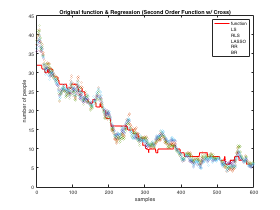

%plot the real function
plot(testy + ym, "r");

%plot the Regression
y_regression_2_cross = [f_LS, f_RLS, f_LASSO, f_RR, f_BR];

hold on
% c = [1 0 0; 0 1 0; 0 0 1; 0 0 0; 0.6350 0.0780 0.1840];
scatter([1:600], y_regression_2_cross, 5);

title("Original function & Regression (Second Order Function w/ Cross)");
xlabel("samples");
ylabel("number of people");
legend(["function", "LS", "RLS", "LASSO", "RR", "BR"]);
hold off

#### Mean Absolute Error and Mean Squared Error

- calAbsoluteErr.m which returns the mean absolute error for the output given a real output 

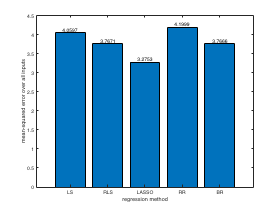

err_squared = zeros(size(y_regression_2_cross, 2), 1);
errlabel = categorical(["LS", "RLS", "LASSO", "RR", "BR"]);
errlabel = reordercats(errlabel,["LS", "RLS", "LASSO", "RR", "BR"]);
for i = 1:size(y_regression_2_cross,2)
    err_squared(i) = calMeanSquaredErr(y_regression_2_cross(:,i), testy + ym);
end
b = bar(errlabel, err_squared);
xlabel("regression method");
ylabel("mean-squared error over all inputs");
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(b.YData);
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

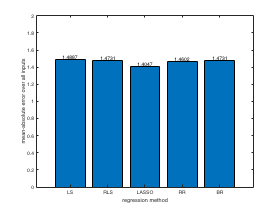


err_abs = zeros(size(y_regression_2_cross, 2), 1);
errlabel = categorical(["LS", "RLS", "LASSO", "RR", "BR"]);
errlabel = reordercats(errlabel,["LS", "RLS", "LASSO", "RR", "BR"]);
for i = 1:size(y_regression_2_cross,2)
    err_abs(i) = calAbsoluteErr(y_regression_2_cross(:,i), testy + ym);
end
b = bar(errlabel, err_abs);
xlabel("regression method");
ylabel("mean-absolute error over all inputs");
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(b.YData);
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
ylim([0 2]);